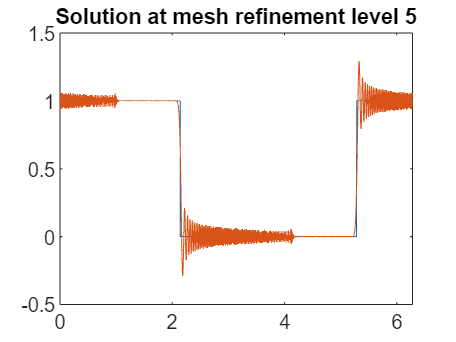

% Sanaz Hami
% 1D Linear Advection Equation with Periodic Initial Condition

% Initialization of parameters
xa = 0;
xb = 2 * pi;
T = 1;
lambda = 0.5;
v0 = @(x) double(mod(x, 2*pi) < pi); % New initial condition
errtab = zeros(5, 2);

% Main loop for mesh refinement
for kk = 1:5
    % Mesh size calculation
    Nx = 100 * (2 ^ (kk - 1)) - 1;
    h = (xb - xa) / (Nx + 1);
    k = h^2;
    % Initialization of solution vector
    v = zeros(1, Nx + 3);
    x = linspace(xa, xb - h, Nx + 1);
    v(2:Nx + 2) = v0(x);        % Apply the new initial condition
    v(1) = v(Nx + 2);           % Ghost point for the right boundary
    v(Nx + 3) = v(2);           % Ghost point for the left boundary

    % Time marching
    v_new = zeros(size(v));
    for ii = 1:floor(T / k)
        for jj = 2:Nx + 2
            v_new(jj) = v(jj) + ((k / h )/ 2) * (v(jj + 1) - v(jj - 1));
        end
        v_new(1) = v_new(Nx + 2);
        v_new(Nx + 3) = v_new(2);
        v = v_new;
    end

    % Final timestep
    for jj = 2:Nx + 2
        v_new(jj) = v(jj) + (((T - floor(T / k) * k) / h) / 2) * (v(jj + 1) - v(jj - 1));
    end
    v = v_new;

    % Calculate numerical error and plot
    u_exac = v0(x + T);
    errtab(kk, 1) = sqrt(sum((u_exac - v(2:Nx + 2)).^2 * h));
    plot(x, u_exac, x, v(2:Nx + 2)); % Plot the exact and numerical solutions
    title(sprintf('Solution at mesh refinement level %d', kk));
    drawnow; % Update the plot
end


% Compute the order of accuracy
for kk = 2:5
    errtab(kk, 2) = log(errtab(kk - 1, 1) / errtab(kk, 1)) / log(2);
end

format shortE;
disp(errtab) % Display the error table

   3.9992e-01            0
   3.1543e-01   3.4239e-01
   2.4941e-01   3.3880e-01
   2.0635e-01   2.7344e-01
   1.5324e-01   4.2928e-01

